rng('default')
rng(1234)
cd /Users/serg/github_projects/QASS_SVM/data
addpath '/Users/serg/Downloads/FixedSize'
% fsllsvm.m modified to export figures

load digits; clear size
[N, dim]=size(X);
Ntest=size(Xtest1,1);
minx=min(min(X)); 
maxx=max(max(X));

noisefactor =1.0;
noise = noisefactor*maxx; % sd for Gaussian noise

Xn = X; 
for i=1:N;
  randn('state', i);
  Xn(i,:) = X(i,:) + noise*randn(1, dim);
end

Xnt = Xtest1; 
for i=1:size(Xtest1,1);
  randn('state', N+i);
  Xnt(i,:) = Xtest1(i,:) + noise*randn(1,dim);
end

%
% select training set
%
Xtr = X(1:1:end,:);



sig2 =dim*mean(var(Xtr)); % rule of thumb
sigmafactor = 0.001;
sig2l=sig2*sigmafactor;

disp(' ');

disp(' Denoise using the first PCs');

 Denoise using the first PCs


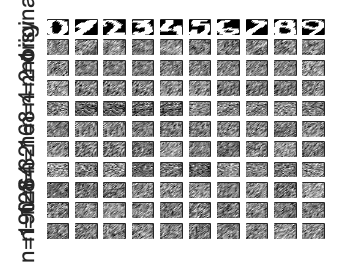

nb_pcs = 1


digit 0 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 1 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 2 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 3 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 4 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 5 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 6 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 7 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 8 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 9 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

nb_pcs = 2


digit 0 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 1 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 2 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 3 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 4 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 5 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 6 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 7 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 8 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 9 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

nb_pcs = 4


digit 0 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 1 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 2 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 3 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 4 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 5 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 6 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 7 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 8 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 9 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

nb_pcs = 8


digit 0 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 1 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 2 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 3 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 4 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 5 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 6 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 7 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 8 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 9 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

nb_pcs = 16


digit 0 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 1 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 2 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 3 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 4 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 5 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 6 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 7 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 8 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 9 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

nb_pcs = 32


digit 0 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 1 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 2 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 3 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 4 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 5 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 6 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 7 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 8 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 9 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

nb_pcs = 64


digit 0 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 1 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 2 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 3 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 4 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 5 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 6 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 7 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 8 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 9 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

nb_pcs = 128


digit 0 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 1 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 2 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 3 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 4 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 5 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 6 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 7 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 8 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 9 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

nb_pcs = 190


digit 0 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 1 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 2 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 3 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 4 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 5 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 6 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 7 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 8 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

digit 9 : 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 


% choose the digits for test
digs=[0:9]; ndig=length(digs);
m=2; % Choose the mth data for each digit 

Xdt=zeros(ndig,dim);


%
% figure of all digits
%
%

% kernel PCA
[lam,U] = kpca(Xtr,'RBF_kernel',sig2l,[],'eig',240); 
[lam, ids]=sort(-lam); lam = -lam; U=U(:,ids);


figure; 
colormap('gray'); 
title('Denosing using linear PCA'); tic


% which number of eigenvalues of kpca
npcs = [2.^(0:7) 190];
lpcs = length(npcs);



for k=1:lpcs;
 nb_pcs=npcs(k); 
 disp(['nb_pcs = ', num2str(nb_pcs)]); 
 Ud=U(:,(1:nb_pcs)); lamd=lam(1:nb_pcs);
    
 for i=1:ndig
   dig=digs(i);
   fprintf('digit %d : ', dig)
   xt=Xnt(i,:);
   if k==1 
     % plot the original clean digits
     %
     subplot(2+lpcs, ndig, i);
     pcolor(1:15,16:-1:1,reshape(Xtest1(i,:), 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     
     if i==1, ylabel('original'), end 
     
     % plot the noisy digits 
     %
     subplot(2+lpcs, ndig, i+ndig); 
     pcolor(1:15,16:-1:1,reshape(xt, 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     if i==1, ylabel('noisy'), end
     drawnow
   end    
   Xdt(i,:) = preimage_rbf(Xtr,sig2l,Ud,xt,'denoise');
   subplot(2+lpcs, ndig, i+(2+k-1)*ndig);
   pcolor(1:15,16:-1:1,reshape(Xdt(i,:), 15, 16)'); shading interp; 
   set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);           
   if i==1, ylabel(['n=',num2str(nb_pcs)]); end
   drawnow    
 end % for i
end % for k

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_321_3.png','Resolution',300)

sig2 =dim*mean(var(Xtr)); % rule of thumb
sigmafactor = 0.1;
sig2m=sig2*sigmafactor 

sig2m = 5.1297


disp(' ');

disp(' Denoise using the first PCs');

 Denoise using the first PCs


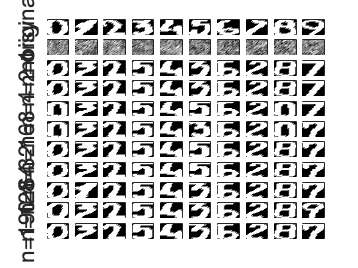

nb_pcs = 1


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 2


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 4


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 8


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 16


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 32


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 64


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 128


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 190


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 


% choose the digits for test
digs=[0:9]; ndig=length(digs);
m=2; % Choose the mth data for each digit 

Xdt=zeros(ndig,dim);


%
% figure of all digits
%
%

% kernel PCA
[lam,U] = kpca(Xtr,'RBF_kernel',sig2m,[],'eig',240); 
[lam, ids]=sort(-lam); lam = -lam; U=U(:,ids);


figure; 
colormap('gray'); 
title('Denosing using linear PCA'); tic


% which number of eigenvalues of kpca
npcs = [2.^(0:7) 190];
lpcs = length(npcs);



for k=1:lpcs;
 nb_pcs=npcs(k); 
 disp(['nb_pcs = ', num2str(nb_pcs)]); 
 Ud=U(:,(1:nb_pcs)); lamd=lam(1:nb_pcs);
    
 for i=1:ndig
   dig=digs(i);
   fprintf('digit %d : ', dig)
   xt=Xnt(i,:);
   if k==1 
     % plot the original clean digits
     %
     subplot(2+lpcs, ndig, i);
     pcolor(1:15,16:-1:1,reshape(Xtest1(i,:), 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     
     if i==1, ylabel('original'), end 
     
     % plot the noisy digits 
     %
     subplot(2+lpcs, ndig, i+ndig); 
     pcolor(1:15,16:-1:1,reshape(xt, 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     if i==1, ylabel('noisy'), end
     drawnow
   end    
   Xdt(i,:) = preimage_rbf(Xtr,sig2m,Ud,xt,'denoise');
   subplot(2+lpcs, ndig, i+(2+k-1)*ndig);
   pcolor(1:15,16:-1:1,reshape(Xdt(i,:), 15, 16)'); shading interp; 
   set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);           
   if i==1, ylabel(['n=',num2str(nb_pcs)]); end
   drawnow    
 end % for i
end % for k


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_321_4.png','Resolution',300)

sig2 =dim*mean(var(Xtr)); % rule of thumb
sigmafactor = 10;
sig2h=sig2*sigmafactor

sig2h = 512.9690



disp(' ');

disp(' Denoise using the first PCs');

 Denoise using the first PCs


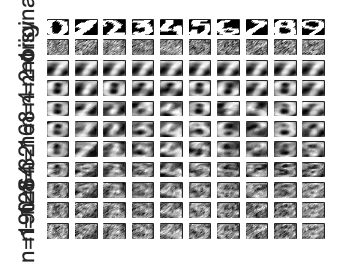

nb_pcs = 1


digit 0 : 

  501> Starting value changed!(d=0) 


digit 1 : digit 2 : digit 3 : digit 4 : 

  501> Starting value changed!(d=0) 


digit 5 : 

    1> Starting value changed!(d=0) 


digit 6 : 

  501> Starting value changed!(d=0) 


digit 7 : digit 8 : digit 9 : 

nb_pcs = 2


digit 0 : digit 1 : digit 2 : 

  501> Starting value changed!(d=0) 


digit 3 : digit 4 : 

  501> Starting value changed!(d=0) 
  503> Starting value changed!(d=0) 
  505> Starting value changed!(d=0) 


digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 4


digit 0 : digit 1 : digit 2 : 

 1000> Maximum iteration reached!


digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : 

  501> Starting value changed!(d=0) 


digit 8 : digit 9 : 

nb_pcs = 8


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : 

 1000> Maximum iteration reached!


digit 8 : digit 9 : 

nb_pcs = 16


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : 

 1000> Maximum iteration reached!


digit 8 : digit 9 : 

nb_pcs = 32


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : 

  501> Starting value changed!(d=0) 
  503> Starting value changed!(d=0) 
  505> Starting value changed!(d=0) 


digit 8 : digit 9 : 

nb_pcs = 64


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : 

  501> Starting value changed!(d=0) 


digit 8 : digit 9 : 

nb_pcs = 128


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : 

  501> Starting value changed!(d=0) 
 1000> Maximum iteration reached!


digit 8 : digit 9 : 

nb_pcs = 190


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : 

  501> Starting value changed!(d=0) 
 1000> Maximum iteration reached!


digit 8 : digit 9 : 


% choose the digits for test
digs=[0:9]; ndig=length(digs);
m=2; % Choose the mth data for each digit 

Xdt=zeros(ndig,dim);


%
% figure of all digits
%
%

% kernel PCA
[lam,U] = kpca(Xtr,'RBF_kernel',sig2h,[],'eig',240); 
[lam, ids]=sort(-lam); lam = -lam; U=U(:,ids);


figure; 
colormap('gray'); 
title('Denosing using linear PCA'); tic


% which number of eigenvalues of kpca
npcs = [2.^(0:7) 190];
lpcs = length(npcs);



for k=1:lpcs;
 nb_pcs=npcs(k); 
 disp(['nb_pcs = ', num2str(nb_pcs)]); 
 Ud=U(:,(1:nb_pcs)); lamd=lam(1:nb_pcs);
    
 for i=1:ndig
   dig=digs(i);
   fprintf('digit %d : ', dig)
   xt=Xnt(i,:);
   if k==1 
     % plot the original clean digits
     %
     subplot(2+lpcs, ndig, i);
     pcolor(1:15,16:-1:1,reshape(Xtest1(i,:), 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     
     if i==1, ylabel('original'), end 
     
     % plot the noisy digits 
     %
     subplot(2+lpcs, ndig, i+ndig); 
     pcolor(1:15,16:-1:1,reshape(xt, 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     if i==1, ylabel('noisy'), end
     drawnow
   end    
   Xdt(i,:) = preimage_rbf(Xtr,sig2h,Ud,xt,'denoise');
   subplot(2+lpcs, ndig, i+(2+k-1)*ndig);
   pcolor(1:15,16:-1:1,reshape(Xdt(i,:), 15, 16)'); shading interp; 
   set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);           
   if i==1, ylabel(['n=',num2str(nb_pcs)]); end
   drawnow    
 end % for i
end % for k


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_321_5.png','Resolution',300)

sig2l

sig2l = 0.0513

sig2m

sig2m = 5.1297

sig2h

sig2h = 512.9690